**Real-time Digital Signal Processing Laboratory**

**Soroush Mesforush Mashhad - 810198472**

clc
clear all

Part 1

Here we read the mefsin.wav file and report its frequency

[Mefsin,Fs] = audioread("mefsin.wav");
disp('The sampling frequency of mefsin.wav in hertz is :');

The sampling frequency of mefsin.wav in hertz is :


disp(Fs)

       16000



Part 2

Here we shall plot the spectrum using FFT

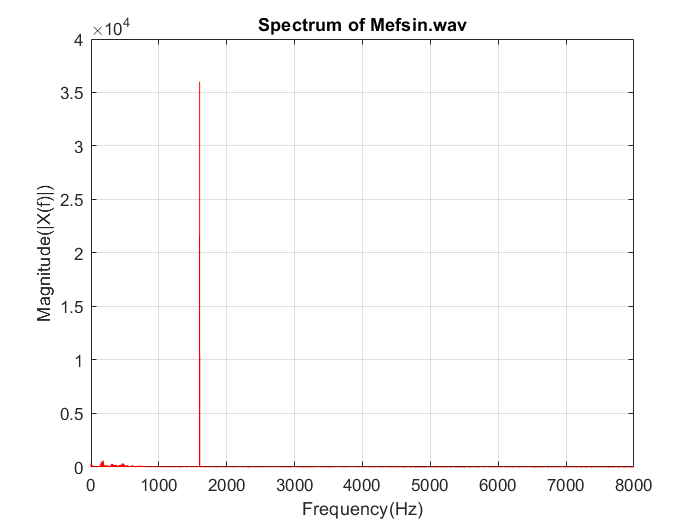

freq = Fs*(0:(length(Mefsin)/2 - 1))/length(Mefsin);
MefF = fftshift(fft(Mefsin));
figure(1)
plot(freq,abs(MefF(end/2+1:end)),'r');
grid on
title('Spectrum of Mefsin.wav');
xlabel('Frequency(Hz)');
ylabel('Magnitude(|X(f)|)');

Here we shall write the Mefsin file into a txt file

Noisy = fopen('Noisy_Monotone.txt','w');
fprintf(Noisy, '%f ',Mefsin);
fclose(Noisy);

Filtered = fopen('MefsinFiltered.txt','r');
FilteredSound = fscanf(Filtered,'%f');
fclose(Filtered);

Here we shall plot the spectrum using FFT

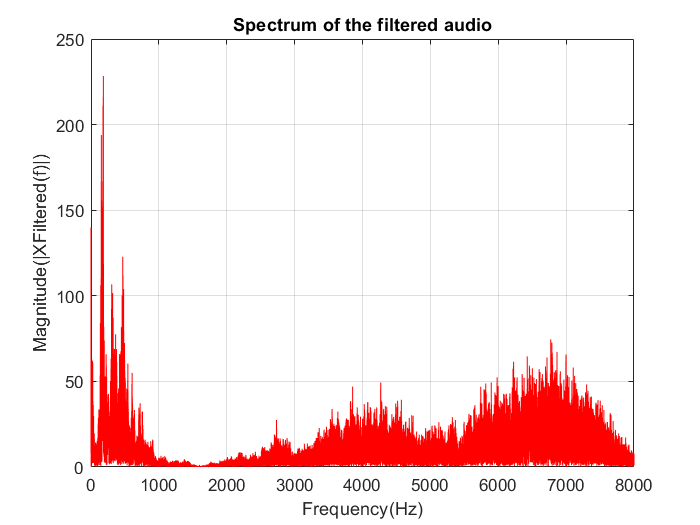

MefNonoiseF = fftshift(fft(FilteredSound));
figure(2)
plot(freq,abs(MefNonoiseF(end/2+1:end)),'r');
grid on
title('Spectrum of the filtered audio');
xlabel('Frequency(Hz)');
ylabel('Magnitude(|XFiltered(f)|)');

Now we write the audio file into a new one and listen to it.

audiowrite('MefsinFiltered.wav',FilteredSound,Fs);